# OGLO notebook 6

HNXJ@github

Instantaneuous phase/freq

% xG = z{9}{1}{1};
xG1 = z{7}{1}{1};
xG2 = z{7}{2}{1};
xG3 = z{7}{3}{1};
xG4 = z{7}{4}{1};
% xG = xG(:, :, :, 1);

phi1 = zeros(6000, 1);
frq1 = zeros(6000-1, 1);
phi2 = zeros(6000, 1);
frq2 = zeros(6000-1, 1);

phi3 = zeros(6000, 1);
frq3 = zeros(6000-1, 1);
phi4 = zeros(6000, 1);
frq4 = zeros(6000-1, 1);

for k = 1:size(xG1, 1)

    xa1 = squeeze(mean(xG1(k, :, :), 2));
    [phiv, frqv] = jInstantSpectrum(xa1, 1000, 50);
    phi1 = phi1 + phiv;
    frq1 = frq1 + frqv;

end

for k = 1:size(xG2, 1)

    xa2 = squeeze(mean(xG2(k, :, :), 2));
    [phiv, frqv] = jInstantSpectrum(xa2, 1000, 50);
    phi2 = phi2 + phiv;
    frq2 = frq2 + frqv;

end

for k = 1:size(xG3, 1)

    xa3 = squeeze(mean(xG3(k, :, :), 2));
    [phiv, frqv] = jInstantSpectrum(xa3, 1000, 50);
    phi3 = phi3 + phiv;
    frq3 = frq3 + frqv;

end

for k = 1:size(xG4, 1)

    xa4 = squeeze(mean(xG4(k, :, :), 2));
    [phiv, frqv] = jInstantSpectrum(xa4, 1000, 50);
    phi4 = phi4 + phiv;
    frq4 = frq4 + frqv;

end

phi1 = phi1 / size(xG1, 1);
frq1 = frq1 / size(xG1, 1);
phi2 = phi2 / size(xG2, 1);
frq2 = frq2 / size(xG2, 1);

phi3 = phi3 / size(xG3, 1);
frq3 = frq3 / size(xG3, 1);
phi4 = phi4 / size(xG4, 1);
frq4 = frq4 / size(xG4, 1);

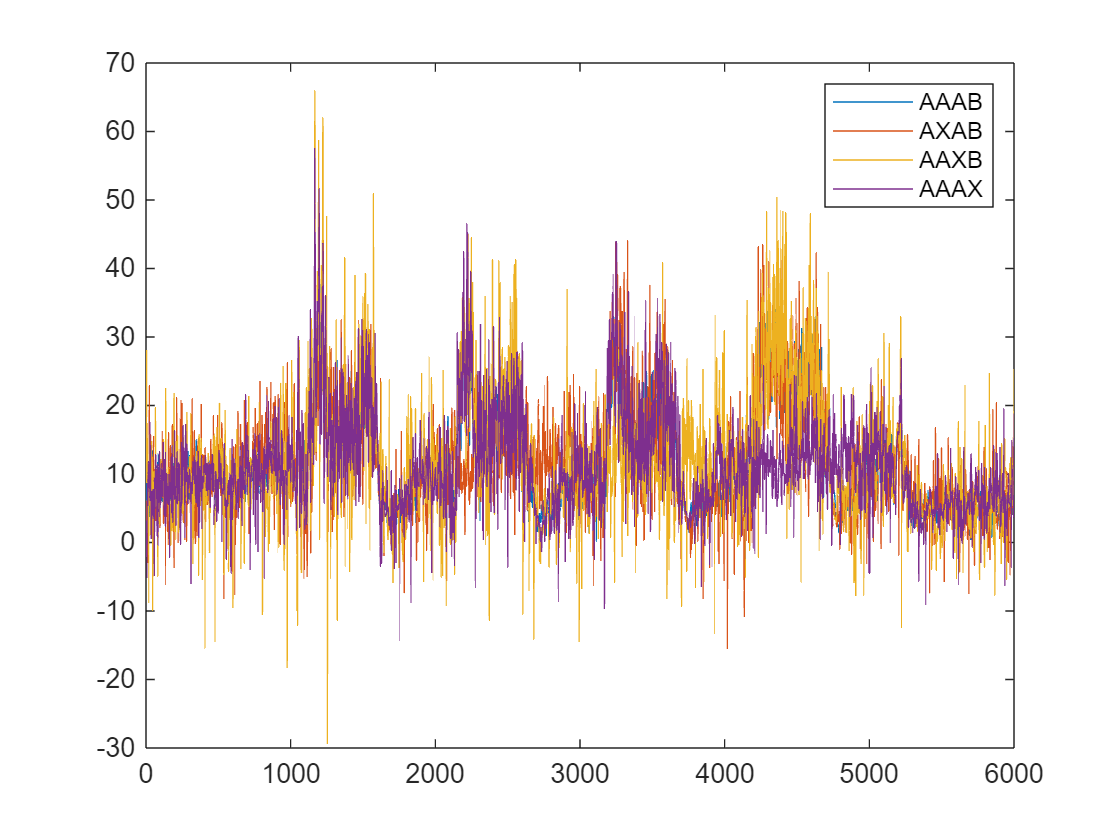

figure;
plot(smooth(frq1, 2), "DisplayName", "AAAB");
hold("on");
plot(smooth(frq2, 2), "DisplayName", "AXAB");
plot(smooth(frq3, 2), "DisplayName", "AAXB");
plot(smooth(frq4, 2), "DisplayName", "AAAX");
legend;

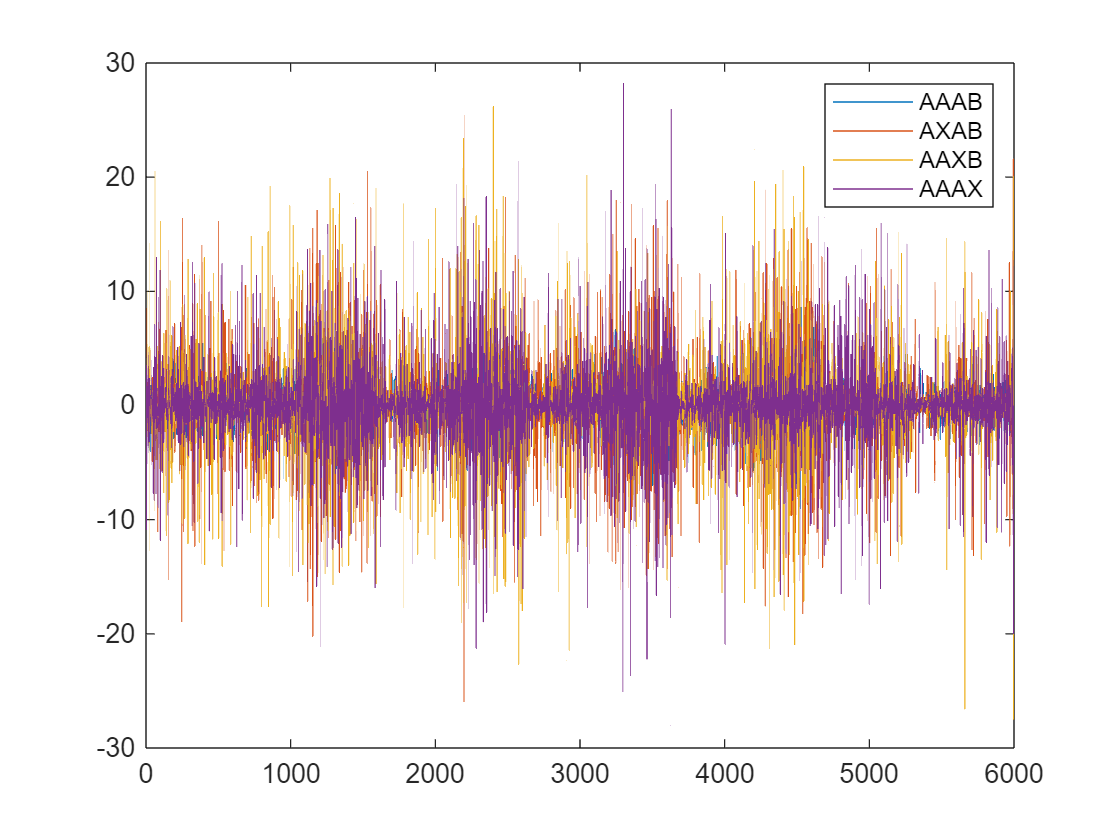

figure;
plot(diff(frq1), "DisplayName", "AAAB");
hold("on");
plot(diff(frq2), "DisplayName", "AXAB");
plot(diff(frq3), "DisplayName", "AAXB");
plot(diff(frq4), "DisplayName", "AAAX");
legend;